# SPIFEE Pipeline Demo


% ------------------------------------------------------------
% This live script demonstrates the SPIFEE analysis pipeline
% using the refactored modular architecture.
%
% The pipeline is executed in five stages:
%   1. loadData
%   2. processData
%   3. extractFeatures
%   4. analyze
%   5. plotResults
%
% This demo uses SPIFEE Programmatically

clear; clc;


## Setup: Define Input Files and SPIFEE params (NO GUI)

% Example dataset
%Script Data Loading
fold = "\ExampleData";
location = pwd() + fold;
Files = dir(location + "/*.mat");
Files = {Files.name};


% 2. DEFINE PARAMETERS (A full description of each parameter that SPIFEE
% uses is shown in full in the DemoInstructions text file.)
params.Field = '';
params.Freq = 5.5;
params.Time = 24;
params.Vert = 1;
params.Norm = "";
params.Fill = 1;
params.Filt = "Default Gaussian";
params.PeakParams = "Default";
params.Thresh = 20;

%Anlaysis [Optional]
params.Clusters = 1;
params.Avg = 1;
params.Means = 1;
params.Name = 'Example';
params.FirstPeak = 1;
params.Heats = 1;
params.Stats = 1;

%Clustering Window
params.Eval = 1;
params.Score = 'CalinskiHarabasz';
params.All = 1;
params.ManClust = "3";
params.ManClustAll = "3";

%Output [Optional]
params.Output = 4;
params.Cond = 1;

warning('off', 'all') %Mute for now.

## Messy Data QC Figures Example

%This is a quick example that demonstrates the qc figures of SPIFEE
fold2 = "\MessyData";
location2 = pwd() + fold2;
Files2 = dir(location2 + "/*.mat");
Files2 = {Files2.name};
params.Vert = 0;
[Files2, location2, params] = Core.loadData(params,Files2, location2);

SPIFEE output folder: Example_2026-05-04_00-04-08


Suggested cutoff for P53_HighAmpNaN: 71 timepoints


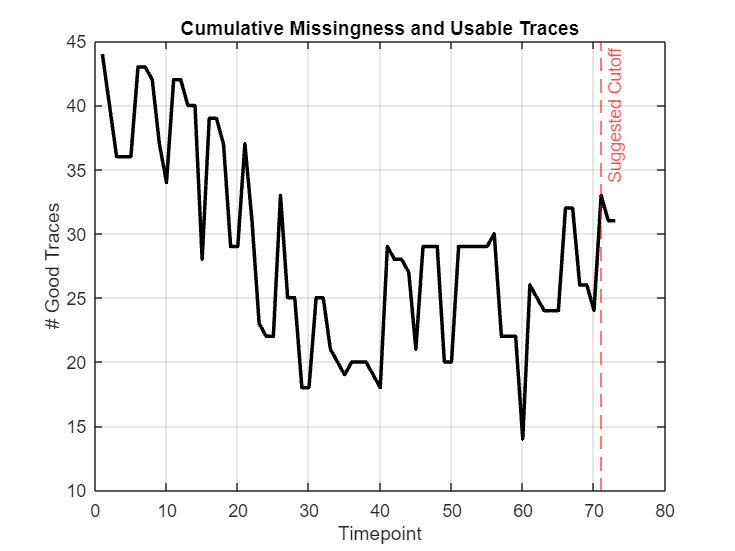

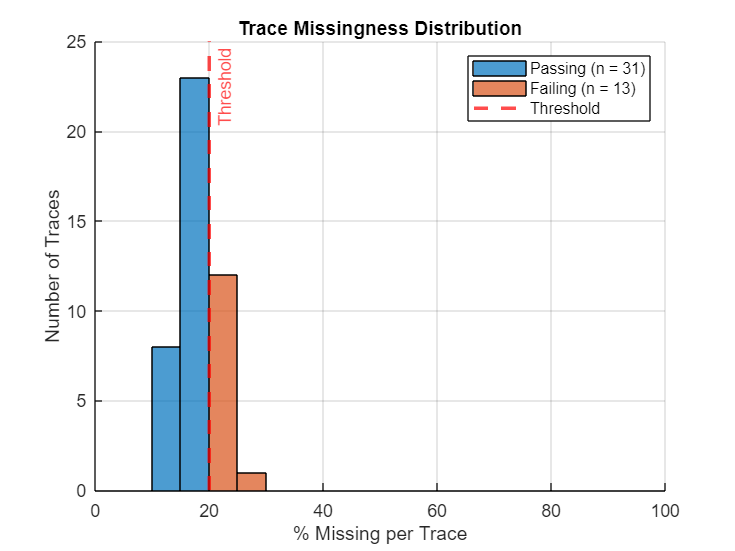

dataStruct2 = Core.processData(Files2, location2, params);

## *Main Pipeline Walkthrough*

## 1. Load Data

params.Vert = 1;
[Files, location, params] = Core.loadData(params, Files, location);

SPIFEE output folder: Example_2026-05-04_00-04-28


disp("Files loaded:")

Files loaded:


disp(Files)

    {'P53_HighAmp.mat'}    {'P53_HighFreq.mat'}    {'P53_LongDuration.mat'}    {'P53_LowAmp.mat'}    {'P53_LowFreq.mat'}    {'P53_Nat.mat'}



## 2. Process Data

dataStruct = Core.processData(Files, location, params);
disp("Processing complete for:")

Processing complete for:


disp({dataStruct.name}')

    {'P53_HighAmp'     }
    {'P53_HighFreq'    }
    {'P53_LongDuration'}
    {'P53_LowAmp'      }
    {'P53_LowFreq'     }
    {'P53_Nat'         }



## 3. Extract Features

featureStruct = Core.extractFeatures(dataStruct, params);
disp("Feature extraction complete")

Feature extraction complete



%% View feature table for first condition
disp(featureStruct(1).Features)

                       Trace1Peak1    Trace1Peak2    Trace1Peak3    Trace2Peak1    Trace2Peak2    Trace2Peak3    Trace3Peak1    Trace3Peak2    Trace3Peak3    Trace4Peak1    Trace4Peak2    Trace4Peak3    Trace5Peak1    Trace5Peak2    Trace5Peak3    Trace6Peak1    Trace6Peak2    Trace6Peak3    Trace7Peak1    Trace7Peak2    Trace7Peak3    Trace8Peak1    Trace8Peak2    Trace8Peak3    Trace8Peak4    Trace8Peak5    Trace9Peak1    Trace9Peak2    Trace9Peak3    Trace9Peak4    Trace10Pe

## 4. Analyze Data

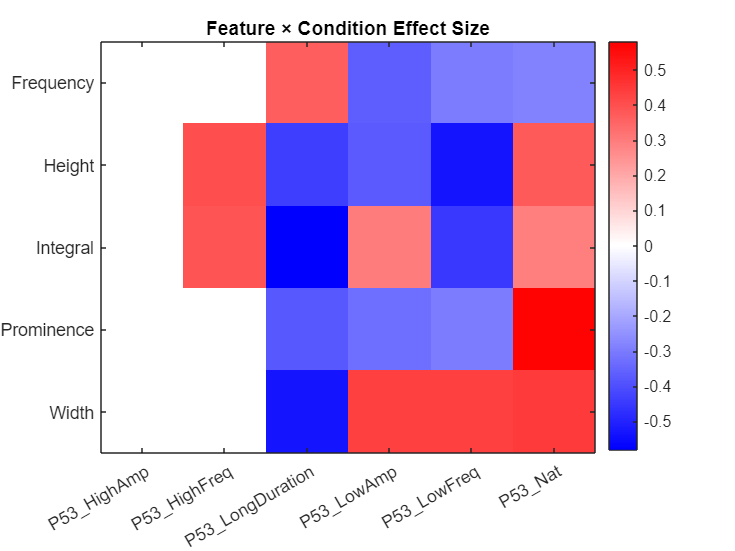

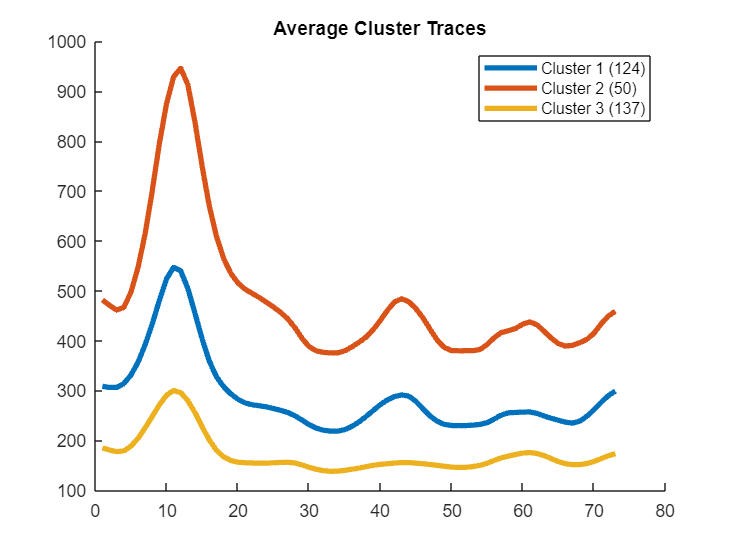

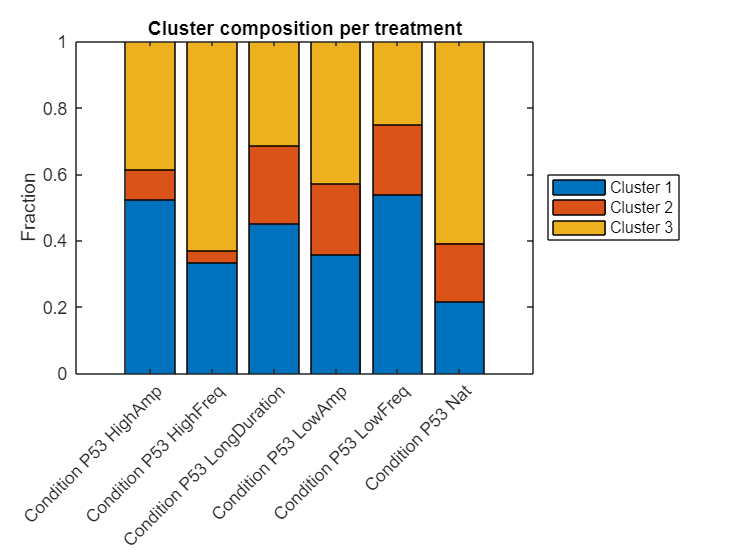

analysisStruct = Core.analyze(featureStruct, params);

%% Key outputs
disp("Conditions:")

Conditions:


disp(analysisStruct.names)

    "P53_HighAmp"    "P53_HighFreq"    "P53_LongDuration"    "P53_LowAmp"    "P53_LowFreq"    "P53_Nat"



## 5. Visualize and Finish

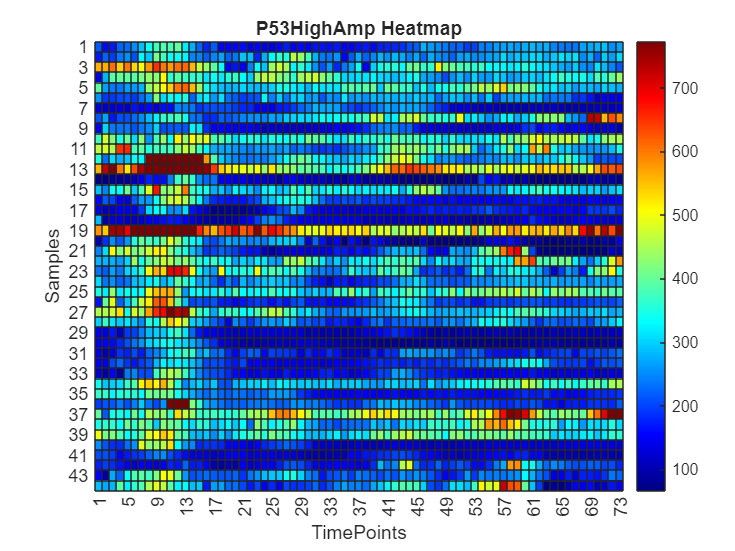

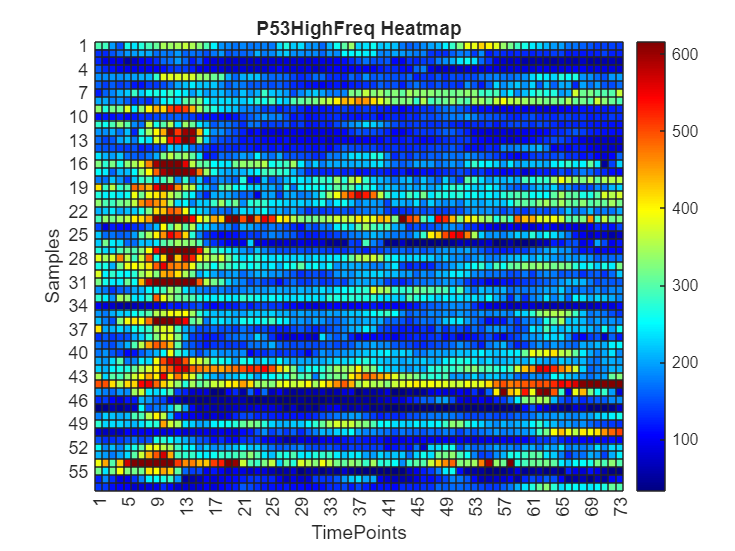

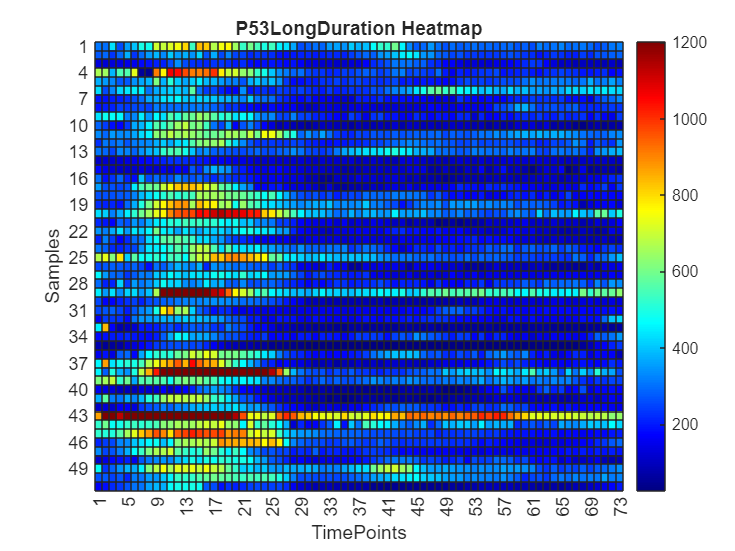

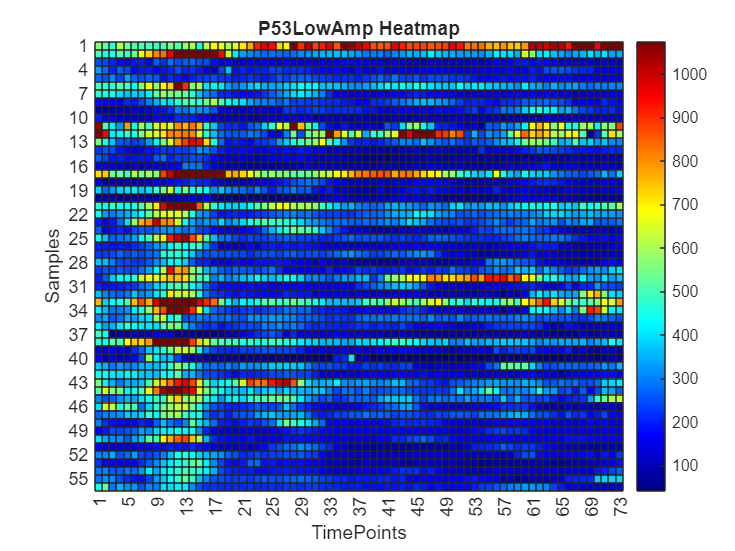

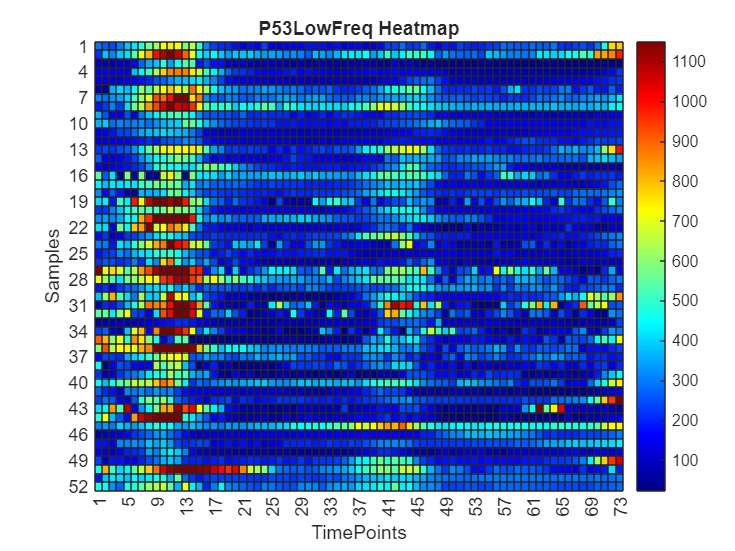

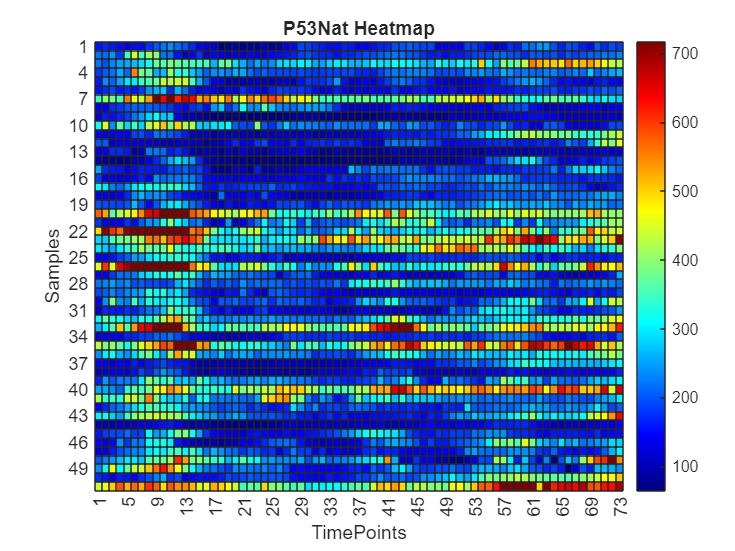

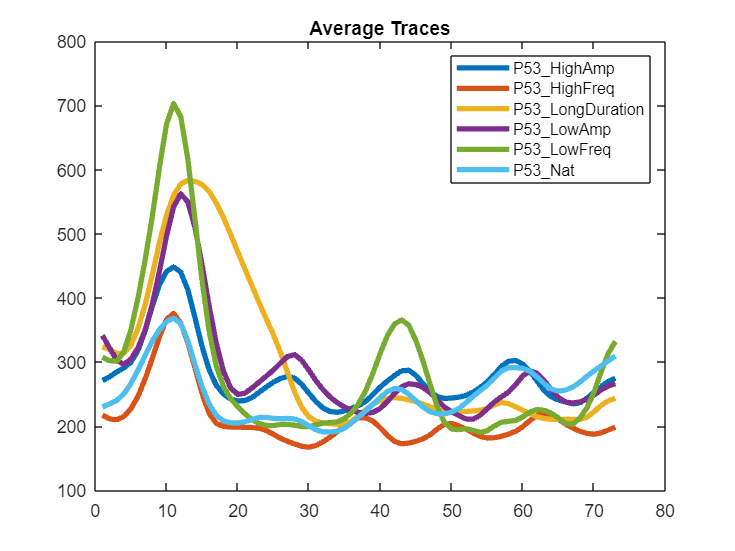

SPIFEE Analysis complete


results = Core.plot_SaveRez(analysisStruct, params);

## Inspect Final Output

disp("Final results fields:")

Final results fields:


disp(fieldnames(results))

    {'Condition_P53_HighAmp'     }
    {'Condition_P53_HighFreq'    }
    {'Condition_P53_LongDuration'}
    {'Condition_P53_LowAmp'      }
    {'Condition_P53_LowFreq'     }
    {'Condition_P53_Nat'         }
    {'AnalysisOrder'             }
    {'AvgTraces'                 }
    {'Stats'                     }
    {'ClusterAllConditionsMeans' }
    {'ClusterAllIndexes'         }
    {'ClusterPercentages'        }
    {'ReprodTxt'                 }



disp("Example Condition Output")

Example Condition Output


disp(results.Condition_P53_Nat)

          Features: [12×152 table]
    FullFiltTraces: [73×51 double]
    SmoothedTraces: [73×51 double]
      TracesUsedID: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
             Means: [5×1 table]
          AvgTrace: [73×1 double]



disp(results.Stats.Significant);

      Feature             Group1                Group2              p          Effect       EffectType      N1     N2       FDR_p       Significant
    ____________    __________________    __________________    __________    ________    ______________    ___    ___    __________    ___________

    "Height"        "P53_HighAmp"         "P53_HighFreq"        2.1317e-07     0.40109    "Cliffs_delta"    134    189    1.2298e-06       true    
    "Height"        "P53_HighFreq"        "P53_LongDuration"    1.0863e-09    -0.43865    "Cliffs_delta"    189    106    1.0184e-08       true    
    "Height"        "P53_HighFreq"        "P53_LowAmp"          2.8

## Show Reproducibility Text Output

if isfield(results, "ReprodTxt")
    disp("Reproducibility Summary:")
    disp(results.ReprodTxt)
end

Reproducibility Summary:


SPIFEE Analysis Summary
------------------------
Analysis Date and Time:
04-May-2026 00:04:47

Software Environment:
9.14.0.2239454 (R2023a) Update 1

Data files used:
 - P53_HighAmp
 - P53_HighFreq
 - P53_LongDuration
 - P53_LowAmp
 - P53_LowFreq
 - P53_Nat

Preprocessing and Data Handling:
--------------------------------
Input traces were analyzed as being over a user-defined duration of 24 hours.
The Data had 44 Traces with 73 points
Data were smoothed using a Gaussian filter derived from a user-specified oscillation frequency of 5.5 hours.
The resulting smoothing window size was 5.5764 points, corresponding to 1/3rd the length of the user's input frequency.

Data was Not Normalized
Data was inputted as being structured Vertically
For NaN values, there was data imputation with fillmissing() with linear interpolation from nearest EndValues.
Only traces with less than 20 percent of points missing were imputed.
Traces exceeding the missing-data threshold of 20% of points were excluded

%End of Demo
disp("SPIFEE demo completed successfully.")

SPIFEE demo completed successfully.
